**Update Log**

1/20/22, cleaning up code to compare timestamps between proc vs unproc NWB's

11/15/21, creating this live script to analyze PDil data

**____________________________________________**

**Set key vars **to direct code to correct files on box & elsewhere

ptPlaceholder = 'pt_01';
day = 1; %can be set to '1' or '2'
block = 1; %can be set from 1-6, 1-2 on day 1, and 3-6 on day 2
dayblockstr = strcat('day', mat2str(day), 'block', mat2str(block))

dayblockstr = 'day1block1'


wireLabel = "RAI";

wireLabelArray = ["LAH"; "LAI"; "LLTL"; "LOF"; "LPH"; "LPI"; "LPT"; "LTP"; "RAH"; "RAI"; "ROF"; "RPH";"RPI"; "RTP"]; %found in the nwbdatainterface obj

rawLoadOn = 0; 
if day == 1
    rawLoadOn = 0; %1/20/22 I only have pt1 postod day2's raw data packaged as an NWB
end


%below vars should be relatively static
dbstop if error
fs = 1000;



Below will need to be changed to load in existing struct so we can append multiple leads 

selectedephysdata = struct();
% selectedephysdata.(ptPlaceholder).(dayblockstr).(char(wireLabel)) = 0;


Add **key base repos**

analysiscode_path = fullfile('/Users','andytekriwal','Desktop','git','emuanalyses_personalrepo', 'pdil');
addpath(genpath(analysiscode_path))

gitgenpersonalToolbox_path = fullfile('/Users','andytekriwal','Desktop','git','personalToolbox');
addpath(genpath(gitgenpersonalToolbox_path))

gitgenseegBRAINplot_s_path = fullfile('/Users','andytekriwal','Desktop','git','seegBRAINplot_s');
addpath(genpath(gitgenseegBRAINplot_s_path))

**Breakpoint** management

% to save out the breakpoints, use below code
saveBrkpoints = 0; %if actively working on, then set this to 0 but if opening fresh set to 1
if saveBrkpoints == 1
    b = dbstatus('-completenames');
    mainBox_AT = fullfile('/Users','andytekriwal','Desktop','git','emuanalyses_personalrepo', 'pdil','Matlab_breakpts');
    cd(mainBox_AT);
    delete buggybrkpnts_PDilSandbox_LiveScript_V2.mat
    save buggybrkpnts_PDilSandbox_LiveScript_V2.mat b;
end

loadOldBrkpoints = 0; %if actively working on, then set this to 0 but if opening fresh set to 1
if loadOldBrkpoints == 1
    load buggybrkpnts_PDilSandbox_LiveScript_V2.mat b
    dbstop(b)
end



Call folder/filenames in order to identify **procesed (meaning downsampled only) NWB**'s & related vars associated with key vars set upstream

if strcmp(ptPlaceholder,'pt_01')
    if day == 1
        ephysfilename = 'PO_Day_02_V2.nwb'; %note that its the V2 format that we're interested in working with, Eli made some changes to the processing pipeline and V2 is what we want
        ephysfilenamemat = 'PO_Day_02.mat';
        behaviorFolderName = 'pt_01_postOpDay2_PDil';
        if block == 1
            behaviorFileName = 'pt01_blockNum_1_computerTT_coop_taskoutput';
            trialindexStart = 1;
        elseif block == 2
            behaviorFileName = 'pt01_blockNum_2_humanTT_coop_taskoutput';
            trialindexStart = 16;
        end
    elseif day == 2
        ephysfilename = 'PO_Day_04_V2.nwb';
        ephysfilenamemat = 'PO_Day_02.mat';
        behaviorFolderName = 'pt_01_postOpDay4_PDil';
        if block == 3
            behaviorFileName = 'pt01_blockNum_3_computerTT_defect_taskoutput';
            trialindexStart = 1;
        elseif block == 4
            behaviorFileName = 'pt01_blockNum_4_humanTT_defect_taskoutput';
            trialindexStart = 16;
        elseif block == 5
            behaviorFileName = 'pt01_blockNum_5_humanTT_coop_taskoutput';
            trialindexStart = 31;
        elseif block == 6
            behaviorFileName = 'pt01_blockNum_6_computerTT_coop_taskoutput';
            trialindexStart = 46;
        end
    end
end

Call folder/filenames for **unprocessed nwb** files (this is only relevant when checking how timestamps match up between processed v unprocessed)


if strcmp(ptPlaceholder,'pt_01')
    if rawLoadOn == 1
        ephysfilenameRaw = 'PO_Day_02_raw.nwb'
    end
end

**git repo unpacking/extraction - need to generate 'core' as API for nwb files before loading in nwb's themselves**

% nwbpackage_analysis_path = fullfile('/Users','andytekriwal','Desktop','git','matnwb');
% addpath(genpath(nwbpackage_analysis_path))

workingFolder_pdil = (fullfile('/Users','andytekriwal','Library','CloudStorage','Box-Box', 'EMU', 'STUDY_PDIL')); %needed to update after upgrating OS systems for macbook
cd(workingFolder_pdil)

Here's some code for cloning relevant git repos

!git clone https://github.com/NeurodataWithoutBorders/matnwb.git

fatal: destination path 'matnwb' already exists and is not an empty directory.


!git clone https://github.com/NeurodataWithoutBorders/nwb-schema

fatal: destination path 'nwb-schema' already exists and is not an empty directory.


For below, we need to 'checkout' the correct version of reader, use the 'util.getSchemaVersion' which is slighty downscript to check if correct version being called for the file in question.

cd nwb-schema
% !git checkout 2.1.0
!git checkout 2.3.0

D	.gitignore
D	.gitmodules
M	bin/find_missing_help.py
M	bin/reformat_spec.py
HEAD is now at 2fc379e Prepare for 2.3.0 release (#475)


cd ../matnwb
!cp -r ../nwb-schema/core nwb-schema/core
addpath(genpath(pwd));
generateCore();


**Load Eli processed NWB**

maindir = fullfile('/Users','andytekriwal','Library','CloudStorage','Box-Box', 'EMU','STUDY_PDIL',ptPlaceholder, 'SEEG', 'processed'); % maindir = uigetdir();
cd(maindir);
util.getSchemaVersion(fullfile('/Users','andytekriwal','Library','CloudStorage','Box-Box', 'EMU','STUDY_PDIL',ptPlaceholder, 'SEEG', 'processed', ephysfilename))

ans = '2.3.0'

nwb_pdil = nwbRead(fullfile('/Users','andytekriwal','Library','CloudStorage','Box-Box', 'EMU','STUDY_PDIL',ptPlaceholder, 'SEEG', 'processed', ephysfilename));

**Utility to navigate **through nwb file, note can also use HDF viewer app, located in git personal toolbox repo > helpful packages

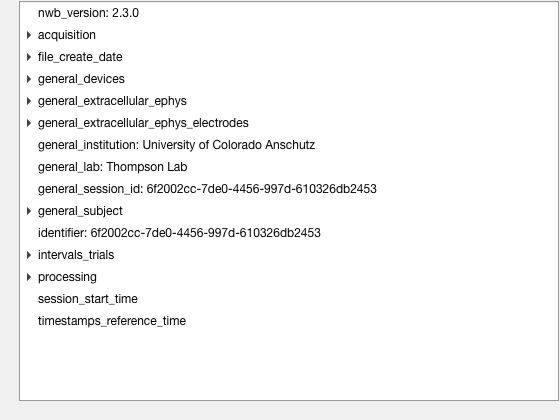

util.nwbTree(nwb_pdil);

As above for **unprocessed** NWB

%% Load unprocessed NWB if applicable
if rawLoadOn == 1
    nwb_pdilraw = nwbRead(fullfile('/Users','andytekriwal','Desktop','PDil_rawdatafiles', ephysfilenameRaw));
    util.nwbTree(nwb_pdilraw);
end

Locate mat unpacked nwb file (1/20/22, idk how useful this is)

% maindir = fullfile('/Users','andytekriwal','Box','EMU','STUDY_PDIL',ptPlaceholder, 'SEEG', 'processed'); % maindir = uigetdir();
% cd(maindir);
% load(ephysfilenamemat)

**Remove line noise (and inc precision using 'double')**

nwb_pdil.processing.get("ecephys");
nwb_pdil.processing.get("ecephys").nwbdatainterface.get(wireLabel);
wireEphys = nwb_pdil.processing.get("ecephys").nwbdatainterface.get(wireLabel).loadAll.data; %key command for nwb format

wireEphys = double(wireEphys);
wireEphys_LN = struct();

neighborsToSample = 3; neighborsToReplace = 1; %Miguel's suggestion for use w/ fx he created
for m = 1:width(wireEphys)
    wireEphys_LN.(char(wireLabel))(:,m) = spectrumInterpolation(wireEphys(:,m), fs, 60, neighborsToSample, neighborsToReplace); % Miguel Parra's function
end

**Fiter - approach taken from 'https://www.ncbi.nlm.nih.gov/pmc/articles/PMC6495648/'**, "we high-pass filtered the raw SEEG signal at 0.5 Hz using a 4th order Butterworth filter to remove slow signal drifts."

filtOrder = 4; hzCutOff = 0.5;
[b,a] = butter(filtOrder,.5/(fs/2),'high');

for m = 1:width(wireEphys)
    wire_Ephys_filtered(:,m) = filter(b, a, wireEphys_LN.(char(wireLabel))(:,m));
end


**Reference using common average by wire, the ephys data**


wireEphys_AVE = mean(wire_Ephys_filtered,2);
for m = 1:width(wire_Ephys_filtered)
    wireEphys_Filt_AND_commonAveRefed(:,m) = (wire_Ephys_filtered(:,m)) - wireEphys_AVE(:);
end


**Gave up on this part (for now, 1/22/22) - add the newly filtered and ref'ed data to the nwb file**

%1/25/22 attemping to add the newly processed data as a distinct module
skipme = 1

skipme = 1

if skipme == 0
    nshanks = 1; %real number TBD
    nchannels_per_shank = 10;
    variables = {'location', 'downsampled', 'filtered', 'referenced', 'group', 'label'};
    tbl = cell2table(cell(0, length(variables)), 'VariableNames', variables);
    device = types.core.Device(...
        'description', 'default', ...
        'manufacturer', 'default' ...
        );
    nwb_pdil.general_devices.set('array', device);
    
    for ishank = 1:nshanks
        electrode_group = types.core.ElectrodeGroup( ...
            'description', ['electrode group for shank' num2str(ishank)], ...
            'location', char(wireLabel), ...
            'device', types.untyped.SoftLink(device) ...
            );
        nwb_pdil.general_extracellular_ephys.set(['shank' num2str(ishank)], electrode_group);
        group_object_view = types.untyped.ObjectView(electrode_group);
        for ielec = 1:nchannels_per_shank
            electrode_label = ['shank' num2str(ishank) 'elec' num2str(ielec)];
            tbl = [...
                tbl; ...
                {char(wireLabel), 1, 1, 1, group_object_view, electrode_label} ...
                ];
        end
    end
    tbl
    
    electrode_table = util.table2nwb(tbl, 'all electrodes');
    nwb_pdil.general_extracellular_ephys_electrodes = electrode_table; %this adds the dynamic table we created to nwb
    
    
    electrode_table_region = types.hdmf_common.DynamicTableRegion( ...
        'table', types.untyped.ObjectView(electrode_table), ...
        'description', char(wireLabel), ...
        'data', (0:height(tbl)-1)');
    
    
    electrical_series = types.core.ElectricalSeries( ...
        'starting_time', 0.0, ... % seconds
        'starting_time_rate', 1000., ... % Hz
        'data', wireEphys_Filt_AND_commonAveRefed, ...
        'electrodes', electrode_table_region, ...
        'data_unit', 'volts');
    
    lfp = types.core.LFP('ElectricalSeries', electrical_series);
    
    ecephys_module = types.core.ProcessingModule(...
        'description', 'extracellular electrophysiology');
    
    ecephys_module.nwbdatainterface.set('LFP', lfp);
    nwb_pdil.processing.set('ecephysII', ecephys_module);
    % util.nwbTree(nwb_pdil);
    
    % %% below is older stuff
    % selectedephys = double(selectedephys); %upsample the precision
    % selectedephys_singlechannel = selectedephys(:,channelnumb);
    % selectedephysdata = struct();
end

**.mat behavior file load in**

Call file/foldernames

maindir = fullfile('/Users','andytekriwal','Library','CloudStorage','Box-Box', 'EMU','STUDY_PDIL',ptPlaceholder, 'Behavioral Data', behaviorFolderName); % maindir = uigetdir();
cd(maindir);
load(behaviorFileName); %all behavioral structs should be loaded in as 'taskoutput'

Behavioral data will load in as struct labeled 'taskoutput', below is an explanation for some of the vars that are contained therein

Intro times, during this portion pts are reading text on screen but otherwise there's nothing going on that is the trial structures themselves:

%below vars are all equivalent/redundant. When summing tictocs, just use
%'taskoutput.timing.Introtime' for consistency.
taskoutput.timing.Introtime;
taskoutput.timing.timing_sumTictocs_Intro;
taskoutput.timing.timing_wholesession_Intro;
taskoutput.timing.Intro_wholesession;

introtime = taskoutput.timing.Introtime;

 if taskoutput.choice_matrix_player1(or2)_logical == 1, means cooperate; whereas == 2 means defect

taskoutput.choice_matrix_player1_logical;


Below are output vars for the coop/trust questions that occur after every 5 blocks

taskoutput.probeResponse_playerAcoop;
taskoutput.probeResponse_playerAtrust;

Total time for post 5 trial questions

% +Time_query1(1)+Time_query1_rxntime(1)+Time_query1_Postrxntime(1)+Time_query2(1)+Time_query2_rxntime(1)+Time_query2_Postrxntime(1);

allTTLs_inSeconds = nwb_pdil.acquisition.get("ttl").timestamps.load; %Gold standard for corroborating timing between behavioral data output and ephys. this is times of all the TTLs
allTrialStarts_inSeconds = nwb_pdil.intervals_trials.loadAll.start_time.data.load; %I think this is same as above except only shows the times for each trial

startTrialsNWB = nwb_pdil.intervals_trials.loadAll.start_time.data.load;
stopTrialsNWB = nwb_pdil.intervals_trials.loadAll.stop_time.data.load;
outcomesNWB = nwb_pdil.intervals_trials.loadAll.vectordata.get("outcome").data.load;

**TTL note: **When we're calculating the 'trialDuration_inSeconds' below, keep in mind that we only have a TTL for the START of each trial, therefore the LAST trial's duration in a given block is going to be off pretty far because the next ttl after the last trial is going to be the start of the next block (if there is another TTL at all).

Below code is set up only for pt01 atm, numbers will need to change based on #blocks/session and whether there was a practice block (which sent TTLs)

blocknumber = str2double(behaviorFileName(15));

%sanity check regarding block# as extracted from behavioral file and block#
%as indicated in key vars at top of script
if blocknumber ~= block
    disp('ERROR: mismatch in stated block numb and extracted block numb')
end

numbPracticeTrials = 0;
if strcmp(ptPlaceholder,'pt_01')
    if blocknumber < 3 %  '<3' because 2 full blocks were run on the first day of testing, which was postop day 2
        numbPracticeTrials = 8;  %  for pt_01, aka 6305, that was CH and pt did 8 practice trials first day along with actual blocks 1 and 2
    end
    if blocknumber == 1
        starttrialnumb = numbPracticeTrials+1;
    elseif blocknumber == 2
        starttrialnumb = numbPracticeTrials+15+1; %because 15 trials/block
    elseif blocknumber > 2
        starttrialnumb = numbPracticeTrials+(((blocknumber)-3)*15)+1; %because 15 trials/block
    end
end

sum(allTrialStarts_inSeconds)

ans = 2.9976e+04

Below, comparing the outputs for timing when summing across tictocs, looking at the whole session tictoc, and looking at sample number for whole session.

%taskoutput.timing_sumTictocs_trial_n) %includes time for questions after 5th trials
timingsum_tictocs = sum(taskoutput.timing_sumTictocs_trial_n) + taskoutput.timing.timing_sumTictocs_introScreens;
timing_wholesession = taskoutput.timing.timing_wholesession;
%below is for calc from ephys, little more involved.
samplenumber_ehpys = length(nwb_pdil.processing.get("ecephys").nwbdatainterface.get(wireLabel).loadAll.data);

recording_wholesession = (samplenumber_ehpys/fs)

recording_wholesession = 1.8899e+03


%below analyses 1st real block after pt block for pt1, pt CH
a = 1;trialDuration_inSeconds = zeros(14,1);
for n = starttrialnumb:(starttrialnumb+13)
    trialDuration_inSeconds(a) = allTrialStarts_inSeconds(n+1)-allTrialStarts_inSeconds(n);
    a = a+1;
end

%for below, remember we don't have the 'next' trial for the last trial of
%the block, so its only 14 not 15 trial timing we're comparing.
timing_wholesession_trial_n = taskoutput.timing_wholesession_trial_n(1:(end-1)); %this is the duration of each trial based on behavior output
% trialDuration_inSeconds = trialDuration_inSeconds(1:(end-1));

%below is the key determination for comparing timing of trials based on
%TTLs and using the behavioral output.
timingDelta_selfcheck_calc = trialDuration_inSeconds - timing_wholesession_trial_n;
mean(abs(timingDelta_selfcheck_calc)) %expect this to be on the order of milliseconds

ans = 0.0046

Assuming that our checks so far have not yielded any issues, now we want to go in and extract some time series data for comparisons that are the most interesting. Here, we'll target the question epochs for comparison/extraction.

%QUESTIONS EPOCH
trialindexStart; %this is the number we want to add to below 3 vars to get place in overall ttl output index
q1_trialnumb = 5;
q2_trialnumb = 10;
q3_trialnumb = 15;

taskoutput.timing_sumTictocs_trial_n; %keep in mind this is the output var for the sum of tictocs in task output

Below is the code for adding timing fx that get us through the entirety of a typical trial's course:

**Probe Questions**


for aa = 1:15
    typicalTrialEventsDuration (aa, 1) = taskoutput.timing.Time_scrn_flip_trials1(aa, 2) + taskoutput.timing.Time_scrn_flip_trials2(aa, 2) + taskoutput.timing.Time_scrn_flip_trials3(aa, 2) + taskoutput.timing.Time_scrn_flip_trials4(aa, 2) + taskoutput.timing.Time_scrn_flip_trials5(aa, 2) + taskoutput.timing.Time_postscrn_flip_trials1(aa,1) + taskoutput.timing.Time_postscrn_flip_trials2(aa,1) + taskoutput.timing.Time_postscrn_flip_trials3(aa,1) + taskoutput.timing.Time_postscrn_flip_trials4(aa,1) + taskoutput.timing.Time_postscrn_flip_trials5(aa,1);
end
n = 1; trialindex_offset = q1_trialnumb;
fifthQuery_coopQuestion_start = typicalTrialEventsDuration (q1_trialnumb, 1) + allTrialStarts_inSeconds(trialindexStart+trialindex_offset);
fifthQuery_coopQuestion_end = fifthQuery_coopQuestion_start + (taskoutput.timing.Time_query1(n) + taskoutput.timing.Time_query1_rxntime(n));
fifthQuery_trustQuestion_start = fifthQuery_coopQuestion_end + (taskoutput.timing.Time_query1_Postrxntime(n));
fifthQuery_trustQuestion_end = fifthQuery_trustQuestion_start + (taskoutput.timing.Time_query2(n) + taskoutput.timing.Time_query2_rxntime(n));

n = 2;trialindex_offset = q2_trialnumb;
tenthQuery_coopQuestion_start = typicalTrialEventsDuration (q2_trialnumb, 1) + allTrialStarts_inSeconds(trialindexStart+trialindex_offset);
tenthQuery_coopQuestion_end = tenthQuery_coopQuestion_start + (taskoutput.timing.Time_query1(n) + taskoutput.timing.Time_query1_rxntime(n));
tenthQuery_trustQuestion_start = tenthQuery_coopQuestion_end + (taskoutput.timing.Time_query1_Postrxntime(n));
tenthQuery_trustQuestion_end = tenthQuery_trustQuestion_start + (taskoutput.timing.Time_query2(n) + taskoutput.timing.Time_query2_rxntime(n));

n = 3;trialindex_offset = q3_trialnumb;
fifteenthQuery_coopQuestion_start = typicalTrialEventsDuration (q3_trialnumb, 1) + allTrialStarts_inSeconds(trialindexStart+trialindex_offset);
fifteenthQuery_coopQuestion_end = fifteenthQuery_coopQuestion_start + (taskoutput.timing.Time_query1(n) + taskoutput.timing.Time_query1_rxntime(n));
fifteenthQuery_trustQuestion_start = fifteenthQuery_coopQuestion_end + (taskoutput.timing.Time_query1_Postrxntime(n));
fifteenthQuery_trustQuestion_end = fifteenthQuery_trustQuestion_start + (taskoutput.timing.Time_query2(n) + taskoutput.timing.Time_query2_rxntime(n));


%lets get the timestamps for ephys recording; n = 1 or trial 5
fifthQuery_coopQuestion_start_timestamp = round((fs* fifthQuery_coopQuestion_start));
fifthQuery_coopQuestion_end_timestamp  = round((fs* fifthQuery_coopQuestion_end));
fifthQuery_trustQuestion_start_timestamp  = round((fs* fifthQuery_trustQuestion_start));
fifthQuery_trustQuestion_end_timestamp  = round((fs* fifthQuery_trustQuestion_end));
%lets get the timestamps for ephys recording; n = 2 or trial 10
tenthQuery_coopQuestion_start_timestamp = round((fs* tenthQuery_coopQuestion_start));
tenthQuery_coopQuestion_end_timestamp  = round((fs* tenthQuery_coopQuestion_end));
tenthQuery_trustQuestion_start_timestamp  = round((fs* tenthQuery_trustQuestion_start));
tenthQuery_trustQuestion_end_timestamp  = round((fs* tenthQuery_trustQuestion_end));
%lets get the timestamps for ephys recording; n = 3 or trial 15
fifteenthQuery_coopQuestion_start_timestamp = round((fs* fifteenthQuery_coopQuestion_start));
fifteenthQuery_coopQuestion_end_timestamp  = round((fs* fifteenthQuery_coopQuestion_end));
fifteenthQuery_trustQuestion_start_timestamp  = round((fs* fifteenthQuery_trustQuestion_start));
fifteenthQuery_trustQuestion_end_timestamp  = round((fs* fifteenthQuery_trustQuestion_end));

probeQuestions_startstop = ...
    [fifthQuery_coopQuestion_start_timestamp,fifthQuery_coopQuestion_end_timestamp ;...
    fifthQuery_trustQuestion_start_timestamp , fifthQuery_trustQuestion_end_timestamp ;...
    tenthQuery_coopQuestion_start_timestamp , tenthQuery_coopQuestion_end_timestamp ;...
    tenthQuery_trustQuestion_start_timestamp , tenthQuery_trustQuestion_end_timestamp ;...
    fifteenthQuery_coopQuestion_start_timestamp, fifteenthQuery_coopQuestion_end_timestamp ;...
    fifteenthQuery_trustQuestion_start_timestamp , fifteenthQuery_trustQuestion_end_timestamp ;]

probeQuestions_startstop =       372964      413690
      414193      423822
      559582      596493
      596995      604395
      710990      736493
      736994      738748



%adding below 2/2/22

%this gives how long each trial was from start to finish, it INCLUDES the
%time for queries after trials 5,10,and 15
timing_wholesession_trial_n;

trialStartTimes = zeros(15,1)

trialStartTimes =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


for aa = 1:15
    if aa == 1
    trialStartTimes(aa) = taskoutput.timing.IntroScreens_wholesession
    elseif aa > 1
        trialStartTimes(aa) = trialStartTimes(aa-1)+taskoutput.timing_wholesession_trial_n(aa-1);
    end        
end

trialStartTimes =    19.4079
         0
         0
         0
         0
         0
         0
         0
         0
         0



% trialStartTimes
% ^so the above variable marks the start time from the first TTL
eventindex = struct();
eventindex.trialStartTimes = trialStartTimes;

for aa = 1:15
    eventindex.initiateTrial(aa) = round(fs* (taskoutput.timing.Time_scrn_flip_trials1(aa,2)+taskoutput.timing.Time_postscrn_flip_trials1(aa)+ allTrialStarts_inSeconds(trialindexStart+aa)));
    eventindex.CandDpromptAppears(aa) = (eventindex.initiateTrial(aa) + taskoutput.timing.Time_scrn_flip_trials2(aa,1)+ allTrialStarts_inSeconds(trialindexStart+aa));
    eventindex.CandDpromptResponseRequest(aa) = (eventindex.initiateTrial(aa) + taskoutput.timing.Time_scrn_flip_trials2(aa,2)+ allTrialStarts_inSeconds(trialindexStart+aa)); %this should be a second later than the above
    eventindex.CandDpromptResponseGiven(aa) = (eventindex.CandDpromptResponseRequest(aa) + taskoutput.timing.Time_postscrn_flip_trials2(aa)+ allTrialStarts_inSeconds(trialindexStart+aa));
    eventindex.spacebarToSeeOpponentsChoice(aa) = (eventindex.CandDpromptResponseGiven(aa)+ taskoutput.timing.Time_scrn_flip_trials3(aa,2)+taskoutput.timing.Time_postscrn_flip_trials3(aa)+taskoutput.timing.Time_scrn_flip_trials4(aa,2)+ allTrialStarts_inSeconds(trialindexStart+aa));
    eventindex.opponentsChoiceOnScreen(aa) = (eventindex.spacebarToSeeOpponentsChoice(aa) + taskoutput.timing.Time_postscrn_flip_trials4(aa)+taskoutput.timing.Time_scrn_flip_trials5(aa,1)+ allTrialStarts_inSeconds(trialindexStart+aa));
    eventindex.doneSeeingOpponentsChoice(aa) = (eventindex.spacebarToSeeOpponentsChoice(aa) + taskoutput.timing.Time_postscrn_flip_trials4(aa)+taskoutput.timing.Time_scrn_flip_trials5(aa,2)+ allTrialStarts_inSeconds(trialindexStart+aa));
end

trialStart_to_CorDselection_startstop = ...%this gives us the time from when trial was initiated with spacebar and when the either C or D response was given by the study pariticpant
    [eventindex.initiateTrial',eventindex.CandDpromptResponseGiven'];

CorDselection_to_doneSeeingOpponentsChoice_startstop = ...%this gives us the time from when trial was initiated with spacebar and when the either C or D response was given by the study pariticpant
    [eventindex.CandDpromptResponseGiven',eventindex.doneSeeingOpponentsChoice']

CorDselection_to_doneSeeingOpponentsChoice_startstop = 	1.0e+05 *

    2.6096    2.6148
    2.9185    2.9243
    3.1544    3.1607
    3.3451    3.3518
    3.6034    3.6106
    3.8735    3.8810
    3.9969    4.0049
    5.1489    5.1592
    5.3399    5.3506
    5.4846    5.4956



% probeQuestions_startstop = ...
%     [fifthQuery_coopQuestion_start_timestamp,fifthQuery_coopQuestion_end_timestamp ;...
%     fifthQuery_trustQuestion_start_timestamp , fifthQuery_trustQuestion_end_timestamp ;...
%     tenthQuery_coopQuestion_start_timestamp , tenthQuery_coopQuestion_end_timestamp ;...
%     tenthQuery_trustQuestion_start_timestamp , tenthQuery_trustQuestion_end_timestamp ;...
%     fifteenthQuery_coopQuestion_start_timestamp, fifteenthQuery_coopQuestion_end_timestamp ;...
%     fifteenthQuery_trustQuestion_start_timestamp , fifteenthQuery_trustQuestion_end_timestamp ;]
% 


The 'meat' of the question period occurs when we have the question on screen, which is    " taskoutput.timing.Time_queryX "   

Followed by the time between when the lykert scale appears and they input a response, which we stored in   " Time_queryX_rxntime "

**Compare TTL output from the processed v unproc nwb files**


allTTLs_inSeconds = nwb_pdil.acquisition.get("ttl").timestamps.load; %Gold standard for corroborating timing between behavioral data output and ephys. this is times of all the TTLs
allTrialStarts_inSeconds = nwb_pdil.intervals_trials.loadAll.start_time.data.load %I think this is same as above except only shows the times for each trial

allTrialStarts_inSeconds = 	1.0e+03 *

    0.2181
    0.2569
    0.2881
    0.3111
    0.3310
    0.3564
    0.3751
    0.3959
    0.5108
    0.5285


if strcmp(ptPlaceholder,'pt_01') && blocknumber == 1
    aa = 9; aaa = 22;
elseif strcmp(ptPlaceholder,'pt_01') && blocknumber == 2
        aa = 24; aaa = 37;
end

a = 1; deltaTrialTime = zeros(15,1);
for n = aa:aaa %note that whatever the range inputted here is, this has to account for whether practice trials occurred
    deltaTrialTime(a,1) = allTrialStarts_inSeconds(n+1) - allTrialStarts_inSeconds(n);
    a = a + 1;
end

%Below is behavior summation for each trial event but doesnt
%count the time for the queries at 5,10,15
typicalTrialEventsDuration;
%Below includes the time for queries as well.
behaviortiming = taskoutput.timing_sumTictocs_trial_n; %keep in mind this is the output var for the sum of tictocs in task output

Comparing the TTL trial length and behavior trial length, looks like we're good at pleast for pt1 block2


deltaTrialTime;
behaviortiming;
comparisonmatrix = [deltaTrialTime,behaviortiming];
comparisonmatrix(:,3) = comparisonmatrix(:,1) - comparisonmatrix(:,2);

**Extract out ephys segments (work in prog)**

channelnumb = 1;
% %below is the output code for diff vars of interest
% timing_sumTictocs_trial_n(queryTime1,1) = timing_sumTictocs_trial_n(queryTime1,1)+Time_query1(1)+Time_query1_rxntime(1)+Time_query1_Postrxntime(1)+Time_query2(1)+Time_query2_rxntime(1)+Time_query2_Postrxntime(1);
% timing_sumTictocs_trial_n(queryTime2,1) = timing_sumTictocs_trial_n(queryTime2,1)+Time_query1(2)+Time_query1_rxntime(2)+Time_query1_Postrxntime(2)+Time_query2(2)+Time_query2_rxntime(2)+Time_query2_Postrxntime(2);
% timing_sumTictocs_trial_n(queryTime3,1) = timing_sumTictocs_trial_n(queryTime3,1)+Time_query1(3)+Time_query1_rxntime(3)+Time_query1_Postrxntime(3)+Time_query2(3)+Time_query2_rxntime(3)+Time_query2_Postrxntime(3) + endScreen;



% nwb_pdil.processing.get("ecephys");
% nwb_pdil.processing.get("ecephys").nwbdatainterface.get("LAH");
% nwb_pdil.processing.get("ecephys").nwbdatainterface.get("LAH").loadAll.data; %GOLD
%
% allTTLs_inSeconds = nwb_pdil.acquisition.get("ttl").timestamps.load; %Gold standard for corroborating timing between behavioral data output and ephys. this is times of all the TTLs
% allTrialStarts_inSeconds = nwb_pdil.intervals_trials.loadAll.start_time.data.load %I think this is same as above except only shows the times for each trial
%
% startTrialsNWB = nwb_pdil.intervals_trials.loadAll.start_time.data.load
% stopTrialsNWB = nwb_pdil.intervals_trials.loadAll.stop_time.data.load
% outcomesNWB = nwb_pdil.intervals_trials.loadAll.vectordata.get("outcome").data.load

% selectedephys = nwb_pdil.processing.get("ecephys").nwbdatainterface.get(wireLabel).loadAll.data; %GOLD

channelNumber = strcat('channel', mat2str(channelnumb))

channelNumber = 'channel1'

% selectedephysdata.(ptPlaceholder).(dayblockstr).(char(wireLabel));%remember this is our master variable

selectedephys = wireEphys_Filt_AND_commonAveRefed(:,channelnumb);
selectedephysdata.(ptPlaceholder).(dayblockstr).(char(wireLabel)).(channelNumber).probeQuestions = 0;
for ii = 1:length(probeQuestions_startstop)
    selectedephysdata.(ptPlaceholder).(dayblockstr).(char(wireLabel)).(channelNumber)(ii).probeQuestions = selectedephys((probeQuestions_startstop(ii, 1)):(probeQuestions_startstop(ii, 2)));
end



trialStart_to_CorDselection_startstop; %this gives us the time from when trial was initiated with spacebar and when the either C or D response was given by the study pariticpant
for ii = 1:length(trialStart_to_CorDselection_startstop)
    selectedephysdata.(ptPlaceholder).(dayblockstr).(char(wireLabel)).(channelNumber)(ii).trialStart_to_CorDselection_startstop= selectedephys((round(trialStart_to_CorDselection_startstop(ii, 1))):round((trialStart_to_CorDselection_startstop(ii, 2))));
end


CorDselection_to_doneSeeingOpponentsChoice_startstop; %this gives us the time from when trial was initiated with spacebar and when the either C or D response was given by the study pariticpant
for ii = 1:length(CorDselection_to_doneSeeingOpponentsChoice_startstop)
    selectedephysdata.(ptPlaceholder).(dayblockstr).(char(wireLabel)).(channelNumber)(ii).CorDselection_to_doneSeeingOpponentsChoice_startstop= selectedephys((round(CorDselection_to_doneSeeingOpponentsChoice_startstop(ii, 1))):round((CorDselection_to_doneSeeingOpponentsChoice_startstop(ii, 2))));
end

2+2



For filtering the ephys signals...

1) referencing and artifact removal

2) downsample (already done)

3) smooth data using filtfilt

4)

**Chronus** and friends workflow, for helpful info on chronux see http://www-users.med.cornell.edu/~jdvicto/pdfs/pubo08.pdf

%'params' is a struct used by chronux to organize relevant vars
params.Fs = fs;
TW = 3; % time-bandwidth product (TW)
K = 5; % number of tapers (K)
params.tapers = [TW K]; % max# tapers can be found by K = ((2*TW) - 1)
params.pad = 1;
params.fpass = [0 fs/2]
p = 0.05
params.err = [1 p];
params.trialavg = 0;

%power spectra
data = selectedephysdata(1).probeQuestions;
[S,f] = mtspectrumc(data, params);
plot_vector(S,f);

figure();
for n = 1:6
    subplot(6,1,n)
    data = selectedephysdata(n).probeQuestions;
    [S,f] = mtspectrumc(data, params);
    plot_vector(S,f)
    hold on
end

figure();
for n = 1:6
    subplot(6,1,n)
    hold
    data = selectedephysdata(n).probeQuestions;
    [S,f, Serr] = mtspectrumc(data, params);
    plot_vector(S,f)
    plot(f,10*log10(Serr(1,:)),'r');
    plot(f,10*log10(Serr(2,:)),'r');
end



%time frequ
windowDuration = 0.5 %units are seconds
windowSlide = 0.05 %time between successive windows, units in seconds
movingwin=[windowDuration windowSlide];
params.fpass = [0 100]


figure()
for n = 1:6
    subplot(6,1,n)
    data = selectedephysdata(n).probeQuestions;
    [S1,t,f]=mtspecgramc(data,movingwin,params);
    plot_matrix(S1,t,f);
    xlabel([]);
%     caxis([8 28]); colorbar;
end

params.fpass = [0 40]
figure()
for n = 1:15
    subplot(3,5,n)
    data = selectedephysdata(n).CorDselection_to_doneSeeingOpponentsChoice_startstop;
    [S1,t,f]=mtspecgramc(data,movingwin,params);
    plot_matrix(S1,t,f);
    xlabel([]);
    colorbar('off')
end



params.fpass = [0 40]
figure()
for n = 1:15
    subplot(3,5,n)
    data = selectedephysdata(n).trialStart_to_CorDselection_startstop;
    [S1,t,f]=mtspecgramc(data,movingwin,params);
    plot_matrix(S1,t,f);
    xlabel([]);
    colorbar('off')
end

%for above plots, repeat but now w/ having a standardize length for half
%second

duration = 500; %remember fs = 1000, so this is half a second

%'params' is a struct used by chronux to organize relevant vars
params.Fs = fs;
TW = 3; % time-bandwidth product (TW)
K = 5; % number of tapers (K)
params.tapers = [TW K]; % max# tapers can be found by K = ((2*TW) - 1)
params.pad = 1;
params.fpass = [0 fs/2];
p = 0.05;
params.err = [1 p];
params.trialavg = 0;
%time frequ
windowDuration = 0.05; %units are seconds
windowSlide = 0.005; %time between successive windows, units in seconds
movingwin=[windowDuration windowSlide];
params.fpass = [0 100];



figure();
for n = 1:6
    subplot(6,1,n)
    hold
    data = selectedephysdata(n).probeQuestions;
    [S,f, Serr] = mtspectrumc(data(end-duration:end), params);
    plot_vector(S,f)
    plot(f,10*log10(Serr(1,:)),'r');
    plot(f,10*log10(Serr(2,:)),'r');
end

figure()
for n = 1:6
    subplot(6,1,n)
    data = selectedephysdata(n).probeQuestions;
    [S1,t,f]=mtspecgramc(data(end-duration:end),movingwin,params);
    plot_matrix(S1,t,f);
    xlabel([]);
%     caxis([8 28]); colorbar;
end

[pxx,f] = pwelch(x,500,300,500,fs);

plot(f,10*log10(pxx))


%1/31/22 lets try to quantify some of the things we see above
% window = 4; %so 250 ms since fs = 1000
% noverlap = round(window*.5);%this is the amount of overlap between adjacent windows
fs = 1000
f = [2, 30];
window = fs*.1;
noverlap = round(window*.5);%this is the amount of overlap between adjacent windows

figure()
for n = 1:6
    
    subplot(6,1,n)
    data = selectedephysdata(n).probeQuestions;
    [pxx,f] = pwelch(data(end-duration:end),window,noverlap,fs,fs);
    plot(f, 10*log10(pxx))

end


[wt,f,coi] = cwt(selectedephysdata(5).probeQuestions,fs); 


figure()
for n = 1:6
    subplot(6,1,n)
    data = selectedephysdata(n).probeQuestions;
    plot(data(end-duration:end));
    xlabel([]);
%     caxis([8 28]); colorbar;
end





%plan is to blackbox tsne it
    tsneInput = [input3_1',input3_2',input4_1',input4_2',input5_1', input7_1',  input9_1', input11_1',  input13_1']; %this is great, created fantastic_tsne4 and 6, I think
    Y = tsne(tsneInput);

Below is copypasta from a signal preprocessing paper

"We removed all channels with excessive line noise from our analyses. To identify these channels, we first calculated a measure of line noise (*LN*) for each channel. Specifically, we applied, at each recording channel, a 2*nd* order IIR peak filter (MATLAB™ iirpeak function) at 50 Hz (i.e., a filter used to retain the 50 Hz frequency component). The output signal was *X**LN*, and 𝐿𝑁=𝑚𝑒𝑎𝑛(𝑋2𝐿𝑁). To calculate a cut-off threshold for noisy channels, we concatenated the filtered signals from all channels of each subject. The concatenation output was *X**LN–all*, and the threshold was set at *median*(*X**LN–all*) + 10 · *mad*(*X**LN–all*), where mad was the mean absolute deviation. Channels whose *LN* exceeded the threshold were discarded. This procedure eliminated 17 out of the total of 2151 channels from further analyses.[3](https://www.ncbi.nlm.nih.gov/pmc/articles/PMC6495648/#FN4)

For all remaining channels, we high-pass filtered the raw SEEG signal at 0.5 Hz using a 4th order Butterworth filter to remove slow signal drifts, and then applied the respective re-referencing method as described above.

After re-referencing, we computed activity in the alpha (8–12 Hz) and broadband gamma (60–140 Hz) bands. To do this, we band-pass filtered the signals at those frequencies using a 6th order Butterworth filter. We then extracted alpha and broadband gamma power by computing the squared absolute value of the Hilbert transform. Finally, we resampled all signals to 1000 Hz prior to subsequent analyses."

in order to access information about the timing of probe questions, will need to subtract off from total trial time duration based on below, keep in mind that

taskoutput.timing_sumTictocs_trial_n = timing_sumTictocs_trial_n

   % taskoutput.probeResponse_playerAcoop = probeResponse_playerAcooperativity;

    taskoutput.timing.Time_query1 = Time_query1;

    taskoutput.timing.Time_query1_rxntime = Time_query1_rxntime;

    taskoutput.timing.Time_query1_Postrxntime = Time_query1_Postrxntime;

    %taskoutput.probeResponse_playerAtrust = probeResponse_playerAtrust;

    taskoutput.timing.Time_query2 = Time_query2;

    taskoutput.timing.Time_query2_rxntime = Time_query2_rxntime;

    taskoutput.timing.Time_query2_Postrxntime = Time_query2_Postrxntime;

    taskoutput.timing.endScreen = endScreen; (NOTE - this only gets added to the final trial (15th))